# LAB 7: STATE-SPACE DESIGN FOR POSITION CONTROL IN A DC MOTOR

%---------------------------------------
% Fill in your group number.
GroupNumber = 29;
% Fill in your student Name and ID.
Students(1).Name = 'Patrick Erath';
Students(1).ID = '260719203';
Students(2).Name = 'Ahmed Said';
Students(2).ID = '260665291';
%---------------------------------------

## **0. Objectives**

In this lab, we will experiment with different controller design to regulate the angular position of a DC Motor. For this we will use state-space representation in `MATLAB` and the function **lsim** to simulate the response of continuous linear systems to arbitrary inputs.

In section 1, we will define the DC Motor model. In section 2, we will design an output feedback controller for angular position control. In section 3, we will study the effect of model mismatch on the output feedback control. Finally, in section 4, we will design a state feedback with an integral component to reduce the disturbance effects.

## **1. State-Space Representation of a DC Motor**

A DC motor can be characterized by the following parameters:

param.Kt = 0.035; % Torque proportionality constant (Kg m2 /s2/A) (N.m/A)
param.Ke = 0.035; % Back electromotive proportionality constant (V/rad/s)
param.L = 5e-3; % Electric inductance (H)
param.R = 0.1; % Terminal resistance (Ohm)
param.J = 5e-4; % Rotor moment of inertia (kg.m2)
param.b = 1e-06; % Rotor viscous friction constant (Kg.m2/s) (N.m.s)

Notice that these parameters differ from the one used for the hardware Qnet DC Motor, and are chosen for the purpose of this lab experiments. The complete state of the DC Motor is represented by $x(t)$


$$ x(t) = \pmatrix{ \theta(t) \cr \omega(t) \cr i(t) } $$


where $\theta(t)$ is the angular position of the rotor, $\omega(t)$ is the angular velocity, and $i(t)$ is the current. The state-space representation of the DC Motor can be written as.


$$ \displaystyle \frac{d}{dt}x(t) = \pmatrix{ -\displaystyle \frac{b}{J}
& \displaystyle \frac{K_t}{J} \cr -\displaystyle \frac{K_e}{L} &
-\displaystyle \frac{R}{L} } x(t) + \pmatrix{ 0 \cr \displaystyle
\frac{1}{L} } v(t) $$


We are interseted on controlling the angular position $$ \theta(t) = \pmatrix{ 1 & 0 & 0} x(t) $$ to track a step input of 90 degrees.

The state-space representation of the DC Motor can be written as.

A = [ ...
    0, 1, 0; ...
    0, -param.b / param.J, param.Kt / param.J; ...
    0, -param.Ke / param.L, -param.R / param.L];
B = [ ...
    0; ...
    0; ...
    1 / param.L];
C = [1, 0, 0];
D = 0;

## **2. Position Control with Output Feedback**

## *2.1 Full state feedback*

In this section we assume that the state $x(t)$ is available at any time. Thus we will design a state feedback controller of the form:


$$v(t) = -K x(t) + N r(t)$$


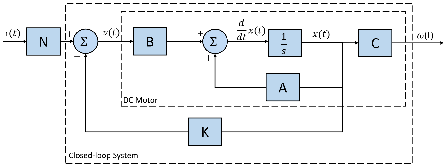

## *Question 1 (0.5 marks)*

Is the system controllable in the proposed state representation?

% [Answer here]
% the system is controllable because there is no T
% in the system

## *Question 2 (2 marks)*

- Design the feedback gain K such that the state feedback places the closed-loop poles at the following locations: $-15 \pm 15 j$, and -150.

- Find the value of the pre-compensator N that will make the steady state error 0.

- Complete the code to test the designed state-feedback controller.

% 1 - [Answer here]


p1d=-15+15*j

p1d = -15.000000000000000 +15.000000000000000i


p2d=-15-15*j

p2d = -15.000000000000000 -15.000000000000000i


p3d=-150

p3d =   -150


Kpoles=[p1d,p2d,p3d]

Kpoles =    1.0e+02 *

 -0.150000000000000 + 0.150000000000000i -0.150000000000000 - 0.150000000000000i -1.500000000000000 + 0.000000000000000i


K=place(A,B, Kpoles)

K =    4.821428571428567   0.318545714571428   0.799990000000000


% 2 - [Answer here]
dcGain=C*(-inv(A-B*K))*B+D

dcGain =    0.207407407407408


N=1/dcGain

N =    4.821428571428567


% 3 - [Answer here]

dt = 1e-3; % sampling time
t = 0:dt:2; % time signal
r = 90 * pi / 180 * ones(size(t)); % reference signal


Hcl= ss(A-B*K, B, C, D) % define the closed loop system


Hcl =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0  -0.002      70
   x3  -964.3  -70.71    -180
 
  B = 
        u1
   x1    0
   x2    0
   x3  200
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



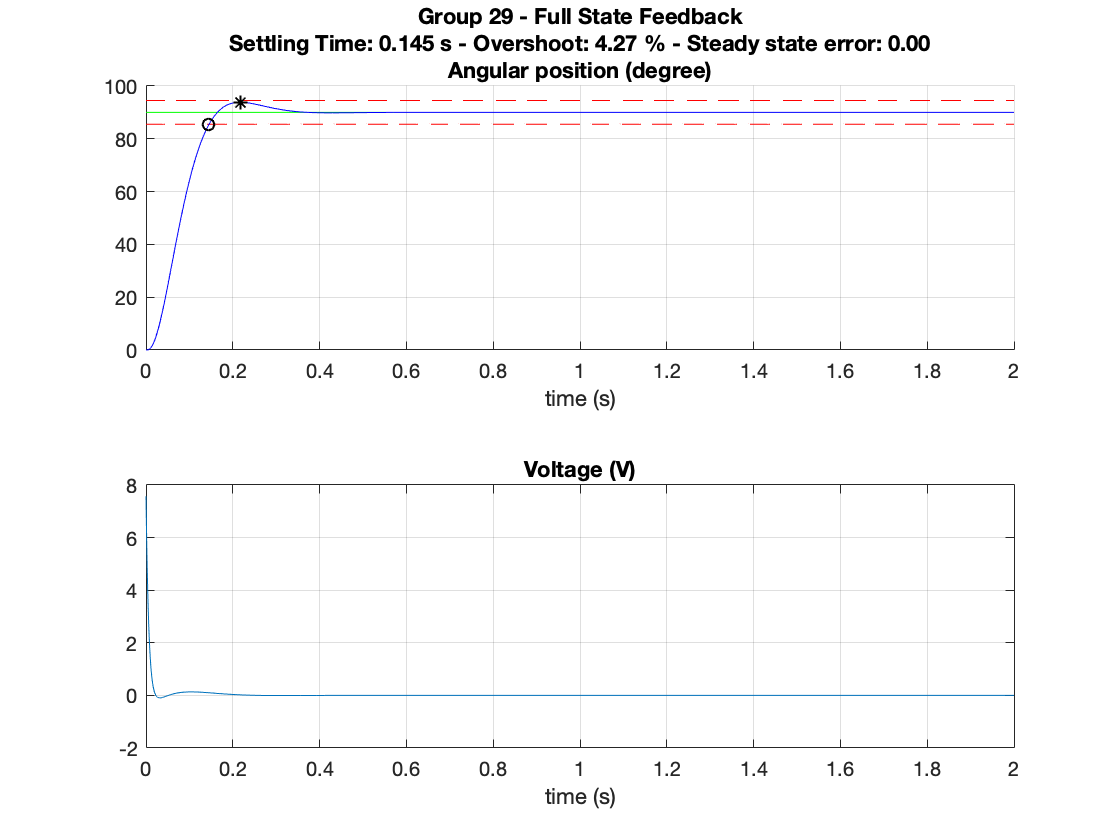



w = lsim(Hcl, N*r, t)'; % simulate the output
v = -K * lsim(ss(Hcl.A, Hcl.B, eye(3), 0), N*r, t)' + N * r; % simulate the command

customStep(sprintf('Group %02d - Full State Feedback',GroupNumber), t, w, r, v)

## *2.2 Output feedback with state observer*

We assume that the state can't be fully measured and only the angular position can be measured. We will design a Luenberger observer based on the known model and the output $\theta(t)$. Recall that the equations of Luenberger observer are:


$$ \displaystyle \frac{d}{dt}\hat{x}(t) = A\hat{x}(t) + B v(t) + L ( C
x(t) - C \hat{x}(t) ) $$


where $L$ is the Luenburguer gain.

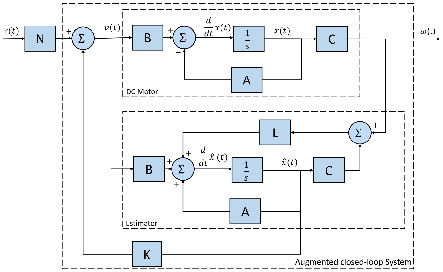

## *Question 3 (0.5 marks)*

Is the system observable in the proposed state representation?

% [Answer here]
%A system is said to be completely state obserable if it has a Luenberger
%observer. Therefore, this system is observable

## *Question 4 (1 marks)*

Design a Luenberger state estimator such that the eigenvalues of the observer are $-10 \pm 10 j$, and -100.

p1=-10+10*j

p1 = -10.000000000000000 +10.000000000000000i


p2=-10-10*j

p2 = -10.000000000000000 -10.000000000000000i


p3=-100

p3 =   -100


Lpoles=[p1,p2,p3]

Lpoles =    1.0e+02 *

 -0.100000000000000 + 0.100000000000000i -0.100000000000000 - 0.100000000000000i -1.000000000000000 + 0.000000000000000i



L=place(A',C', Lpoles)'

L =    1.0e+02 *

   0.999980000000000
  -2.901999959999975
  -3.314145714285718


The state space representation of the output feedback system with a state observer can be represented by the augmented state:


$$ x_{aug}(t) = \pmatrix{ x(t) \cr \hat{x}(t)} $$


and the feedback law is:


$$ v(t) = -K \hat{x}(t) + N r $$


With these notations, we can write the augmented state space equations as a function of A, B, C, K, and L


$$ \displaystyle \frac{d}{dt}x_{aug}(t) = \pmatrix{ A & -B K \cr L C & A
- L C - B K} x_{aug}(t) + \pmatrix{B \cr B} v(t) $$


## *Question 5 (1.5 marks)*

- Write the augmented state-space representation matrices $A_{aug}$ and $B_{aug}$.

- Complete the code to simulate the response of output feedback system to follow a step input (use the same feedback gain $N$, and $K$ from section 1.1).

% 1 - [Answer here]

Aaug= [A , (-B*K) ; (L*C) , (A-(L*C)-(B*K))]

Aaug =    1.0e+02 *

                   0   0.010000000000000                   0                   0                   0                   0
                   0  -0.000020000000000   0.700000000000000                   0                   0                   0
                   0  -0.070000000000000  -0.200000000000000  -9.642857142857133  -0.637091429142856  -1.599980000000000
   0.999980000000000                   0                   0  -0.999980000000000   0.010000000000000                   0
  -2.901999959999975                   0                   0   2.901999959999975  -0.000020000000000   0.700000000000000
  -3.314145714285718                   0                   0  -6.328711428571415  -0.707091429142856  -1.799980000000000



Baug= [B; B]

Baug =      0
     0
   200
     0
     0
   200




% 2 - [Answer here]
Caug = [1, 0, 0, 0, 0, 0];


Hcl=ss(Aaug, Baug, Caug, D) % define the augmented closed loop system


Hcl =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       1       0       0       0       0
   x2       0  -0.002      70       0       0       0
   x3       0      -7     -20  -964.3  -63.71    -160
   x4     100       0       0    -100       1       0
   x5  -290.2       0       0   290.2  -0.002      70
   x6  -331.4       0       0  -632.9  -70.71    -180
 
  B = 
        u1
   x1    0
   x2    0
   x3  200
   x4    0
   x5    0
   x6  200
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



w=lsim(Hcl, N*r, t)' % simulate the output

w =   Columns 1 through 499

   0.000000000000000   0.000016899903511   0.000129387145372   0.000418195513137   0.000949948564063   0.001779169309314   0.002950009907927   0.004497740353074   0.006450029703719   0.008828048741672   0.011647418911821   0.014919028941369   0.018649737554162   0.022842978131495   0.027499278963330   0.032616710833850   0.038191272049961   0.044217219613744   0.050687354028396   0.057593264184405   0.064925537875188   0.072673942718910   0.080827581598275   0.089375026157781   0.098304431405323   0.107603634041046   0.117260236771395   0.127261680552201   0.137595306434278   0.148248408452270   0.159208278797189   0.170462246340670   0.181997709430557   0.193802163749682   0.205863225919756   0.218168653437635   0.230706361449753   0.243464436800367   0.256431149728922   0.269594963539842   0.282944542523332   0.296468758367266   0.310156695267068   0.323997653911966   0.337981154501408   0.352096938924278   0.366334972215344   0.380685443387649   0.395138

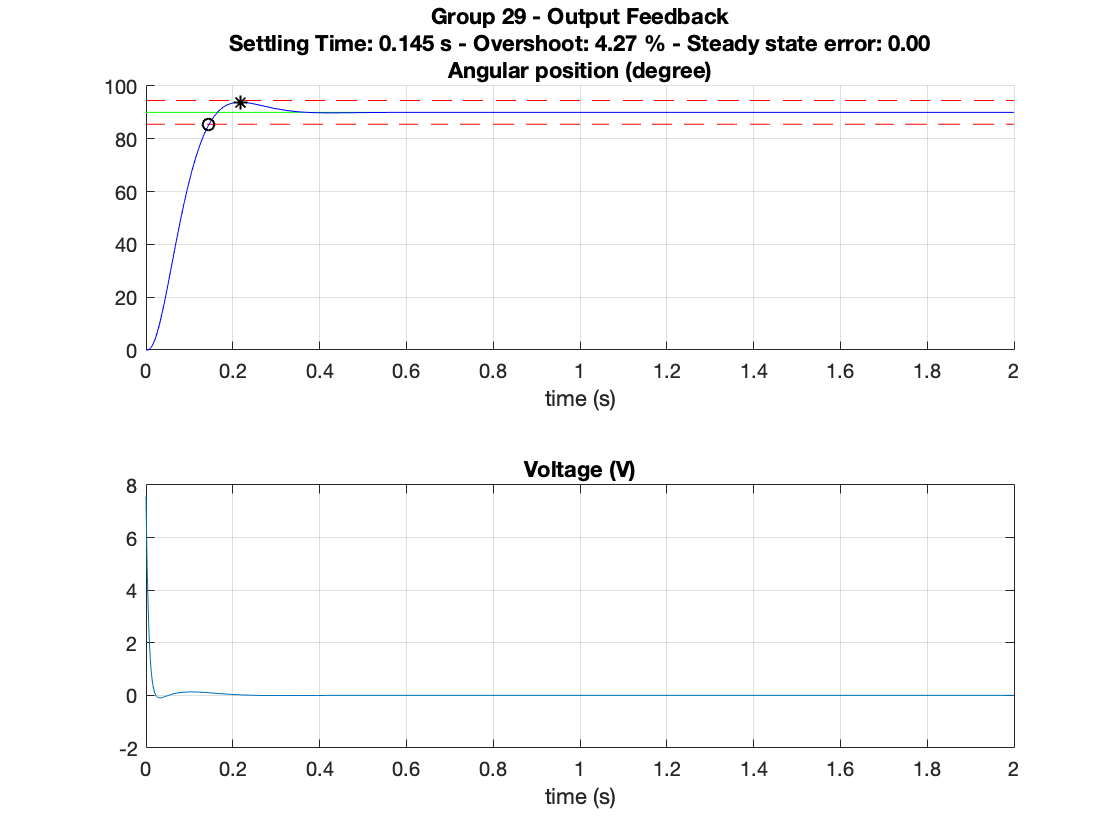



w = w(:)'; % make the output a row array
v = -K * lsim(ss(Hcl.A, Hcl.B, [zeros(3), eye(3)], 0), N*r, t)' + N * r; % simulate the command

customStep(sprintf('Group %02d - Output Feedback',GroupNumber), t, w, r, v)

## *Question 6 (1 marks)*

Let's change the Luenberger gain such as the observer dynamic is 10 times slower. re-run the experiment. What do you observe ? Justify your answer.

Lnewpoles = 0.1 * Lpoles;

Lnew = place(A', C', Lnewpoles)';

K = place(A, B, Kpoles);

Aaug = [A , (-B*K) ; (Lnew*C) , (A-(Lnew*C)-(B*K))]

Aaug =    1.0e+03 *

                   0   0.001000000000000                   0                   0                   0                   0
                   0  -0.000002000000000   0.070000000000000                   0                   0                   0
                   0  -0.007000000000000  -0.020000000000000  -0.964285714285713  -0.063709142914286  -0.159998000000000
  -0.008002000000000                   0                   0   0.008002000000000   0.001000000000000                   0
  -0.307983996000003                   0                   0   0.307983996000003  -0.000002000000000   0.070000000000000
   0.144299714285716                   0                   0  -1.108585428571429  -0.070709142914286  -0.179998000000000



Baug = [B; B]

Baug =      0
     0
   200
     0
     0
   200



Caug = [1, 0, 0, 0, 0, 0];

Hcl = ss(Aaug, Baug, Caug, D) % define the closed loop system


Hcl =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       1       0       0       0       0
   x2       0  -0.002      70       0       0       0
   x3       0      -7     -20  -964.3  -63.71    -160
   x4  -8.002       0       0   8.002       1       0
   x5    -308       0       0     308  -0.002      70
   x6   144.3       0       0   -1109  -70.71    -180
 
  B = 
        u1
   x1    0
   x2    0
   x3  200
   x4    0
   x5    0
   x6  200
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



w = lsim(Hcl, N*r, t)' % simulate the output

w =   Columns 1 through 499

   0.000000000000000   0.000016899903511   0.000129387145372   0.000418195513137   0.000949948564063   0.001779169309314   0.002950009907927   0.004497740353074   0.006450029703719   0.008828048741672   0.011647418911821   0.014919028941369   0.018649737554162   0.022842978131496   0.027499278963330   0.032616710833850   0.038191272049961   0.044217219613744   0.050687354028396   0.057593264184405   0.064925537875188   0.072673942718910   0.080827581598276   0.089375026157781   0.098304431405323   0.107603634041046   0.117260236771395   0.127261680552201   0.137595306434279   0.148248408452271   0.159208278797189   0.170462246340670   0.181997709430558   0.193802163749682   0.205863225919756   0.218168653437636   0.230706361449753   0.243464436800367   0.256431149728922   0.269594963539842   0.282944542523333   0.296468758367266   0.310156695267069   0.323997653911967   0.337981154501408   0.352096938924279   0.366334972215345   0.380685443387649   0.395138

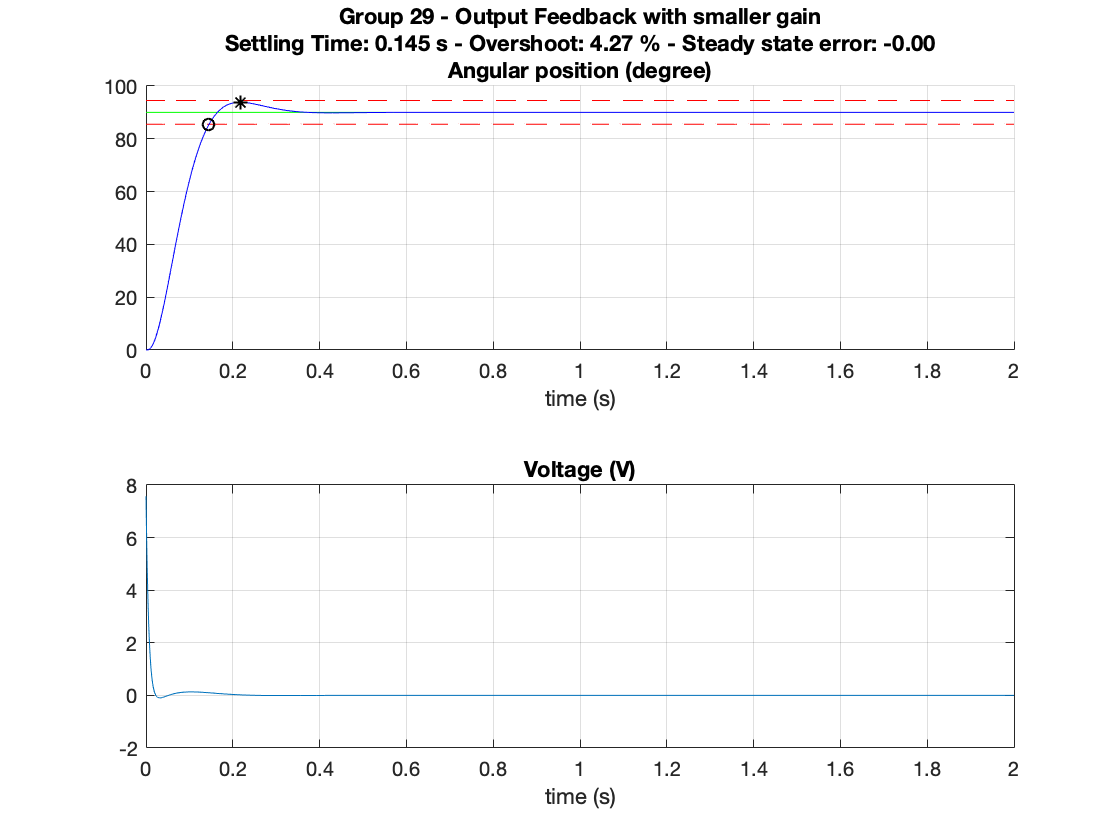



w = w(:)'; % make the output a row array
v = -K * lsim(ss(Hcl.A, Hcl.B, [zeros(3), eye(3)], 0), N*r, t)' + N * r; % simulate the command

customStep(sprintf('Group %02d - Output Feedback with smaller gain',GroupNumber), t, w, r, v)

%  What do you observe ?
% we observe that the two graphs are the same

## **3. Effects of wrong model**

As seen in section 2 the importance of the Luenberger estimator will only be visible in case the dynamics of the model are not completely known. For example, in this section we assume that in the real DC Motor the inertia is 3 times what we initially thought. Which means that the true dynamics of the DC Motor are:

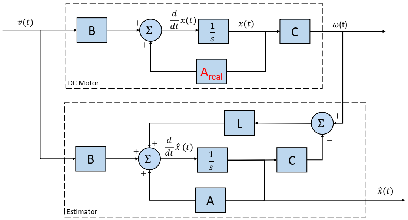

Jreal = 3 * param.J;

Areal = [ ...
    0, 1, 0; ...
    0, -param.b / Jreal, param.Kt / Jreal; ...
    0, -param.Ke / param.L, -param.R / param.L];

For the purpose of this experiment we assume that we don't know about the true $A_{real}$ and we only use $A$ in the estimator dynamics.

## *Question 7 (1.5 marks)*

- Re-run the experiment using the same gains $N$, $K$, and $L$. But this time replace the transition matrix of the state space model of the DC Motor by $A_{real}$. What do you observe ?

- Change the design of $L$ such as the observer is 5 times faster. What do you observe ?

% 1 -

Aaug=[Areal , (-B*K) ; (L*C) , (Areal-(L*C)-(B*K))]

Aaug =    1.0e+02 *

                   0   0.010000000000000                   0                   0                   0                   0
                   0  -0.000006666666667   0.233333333333333                   0                   0                   0
                   0  -0.070000000000000  -0.200000000000000  -9.642857142857133  -0.637091429142856  -1.599980000000000
   0.999980000000000                   0                   0  -0.999980000000000   0.010000000000000                   0
  -2.901999959999975                   0                   0   2.901999959999975  -0.000006666666667   0.233333333333333
  -3.314145714285718                   0                   0  -6.328711428571415  -0.707091429142856  -1.799980000000000



Baug=[B; B]

Baug =      0
     0
   200
     0
     0
   200



Hcl = ss(Aaug, Baug, Caug, D) % define the closed loop system


Hcl =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           1           0           0           0           0
   x2           0  -0.0006667       23.33           0           0           0
   x3           0          -7         -20      -964.3      -63.71        -160
   x4         100           0           0        -100           1           0
   x5      -290.2           0           0       290.2  -0.0006667       23.33
   x6      -331.4           0           0      -632.9      -70.71        -180
 
  B = 
        u1
   x1    0
   x2    0
   x3  200
   x4    0
   x5    0
   x6  200
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



w =  lsim(Hcl, N*r, t)' % simulate the output

w =   Columns 1 through 499

   0.000000000000000   0.000005634220752   0.000043156827279   0.000139597916293   0.000317444599159   0.000595353958969   0.000988753923425   0.001510349682275   0.002170550505340   0.002977829480565   0.003939026722383   0.005059604941330   0.006343864867427   0.007795126841369   0.009415883894509   0.011207930801666   0.013172472885559   0.015310217757284   0.017621452676429   0.020106109792290   0.022763821172004   0.025593965221603   0.028595705853450   0.031768025540583   0.035109753219146   0.038619587848868   0.042296118314201   0.046137840241299   0.050143170215618   0.054310457808607   0.058637995757752   0.063124028590065   0.067766759933486   0.072564358722218   0.077514964469592   0.082616691754775   0.087867634046606   0.093265866968443   0.098809451091586   0.104496434331054   0.110324854005868   0.116292738616258   0.122398109381929   0.128638981578583   0.135013365704059   0.141519268500507   0.148154693854846   0.154917643596270   0.161806

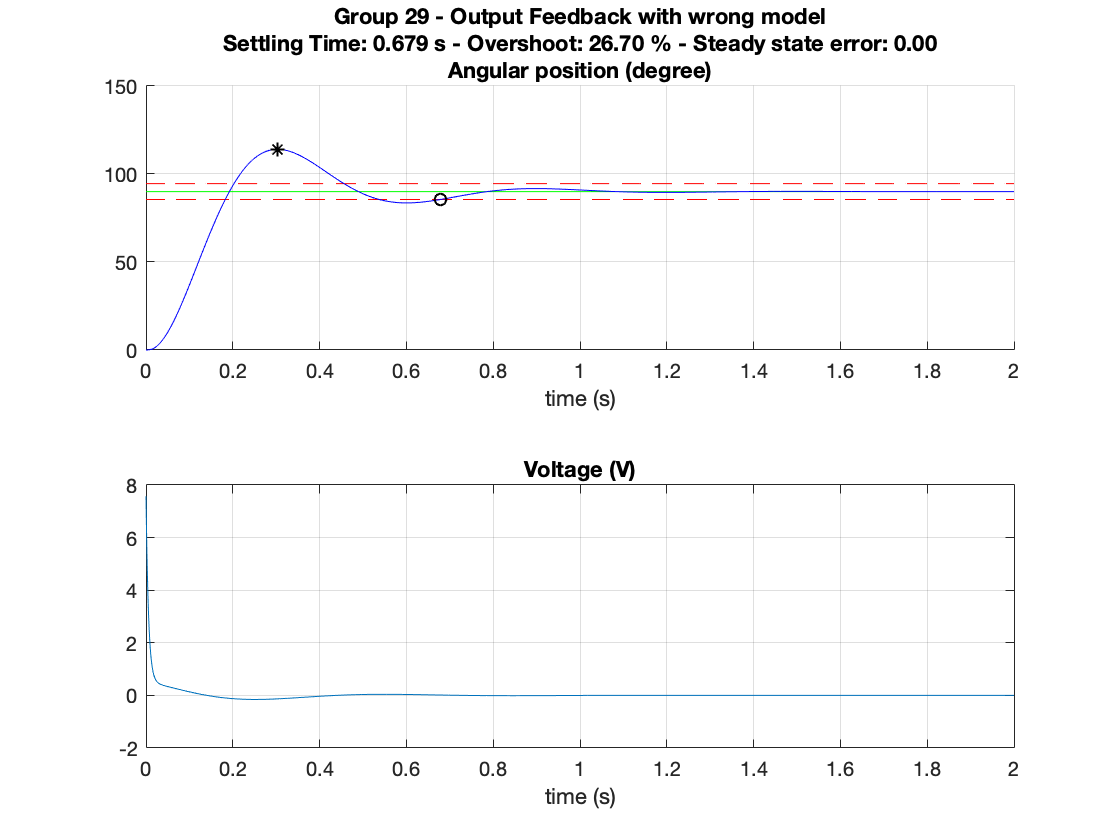



w = w(:)'; % make the output a row array
v = -K * lsim(ss(Hcl.A, Hcl.B, [zeros(3), eye(3)], 0), N*r, t)' + N * r; % simulate the command

customStep(sprintf('Group %02d - Output Feedback with wrong model',GroupNumber), t, w, r, v)

% What do you observe
%  It can be observed that there is an increase in both the settling time and the overshoot from
%from the previous graphs

% 2 -

Lnewpoles = 5*Lpoles % set this value to 5*Lpoles

Lnewpoles =    1.0e+02 *

 -0.500000000000000 + 0.500000000000000i -0.500000000000000 - 0.500000000000000i -5.000000000000000 + 0.000000000000000i



Lnew = place(A', C', Lnewpoles)';

K = place(A, B, Kpoles);
   
Aaug = [A , (-B*K) ; (Lnew*C) , (A-(Lnew*C)-(B*K))]

Aaug =    1.0e+04 *

                   0   0.000100000000000                   0                   0                   0                   0
                   0  -0.000000200000000   0.007000000000000                   0                   0                   0
                   0  -0.000700000000000  -0.002000000000000  -0.096428571428571  -0.006370914291429  -0.015999800000000
   0.057999799999999                   0                   0  -0.057999799999999   0.000100000000000                   0
   4.290884000399999                   0                   0  -4.290884000399999  -0.000000200000000   0.007000000000000
   1.939429971428576                   0                   0  -2.035858542857147  -0.007070914291429  -0.017999800000000



Baug=[B; B]

Baug =      0
     0
   200
     0
     0
   200



Hcl =ss(Aaug, Baug, Caug, D) % define the closed loop system


Hcl =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           1           0           0           0           0
   x2           0      -0.002          70           0           0           0
   x3           0          -7         -20      -964.3      -63.71        -160
   x4         580           0           0        -580           1           0
   x5   4.291e+04           0           0  -4.291e+04      -0.002          70
   x6   1.939e+04           0           0  -2.036e+04      -70.71        -180
 
  B = 
        u1
   x1    0
   x2    0
   x3  200
   x4    0
   x5    0
   x6  200
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



w = lsim(Hcl, N*r, t)' % simulate the output

w =   Columns 1 through 499

   0.000000000000000   0.000016899903511   0.000129387145372   0.000418195513137   0.000949948564063   0.001779169309314   0.002950009907927   0.004497740353074   0.006450029703719   0.008828048741672   0.011647418911821   0.014919028941369   0.018649737554162   0.022842978131495   0.027499278963330   0.032616710833850   0.038191272049961   0.044217219613744   0.050687354028396   0.057593264184405   0.064925537875188   0.072673942718910   0.080827581598275   0.089375026157781   0.098304431405323   0.107603634041046   0.117260236771395   0.127261680552201   0.137595306434278   0.148248408452270   0.159208278797189   0.170462246340670   0.181997709430557   0.193802163749682   0.205863225919755   0.218168653437635   0.230706361449753   0.243464436800367   0.256431149728922   0.269594963539842   0.282944542523332   0.296468758367266   0.310156695267068   0.323997653911966   0.337981154501408   0.352096938924278   0.366334972215344   0.380685443387648   0.395138

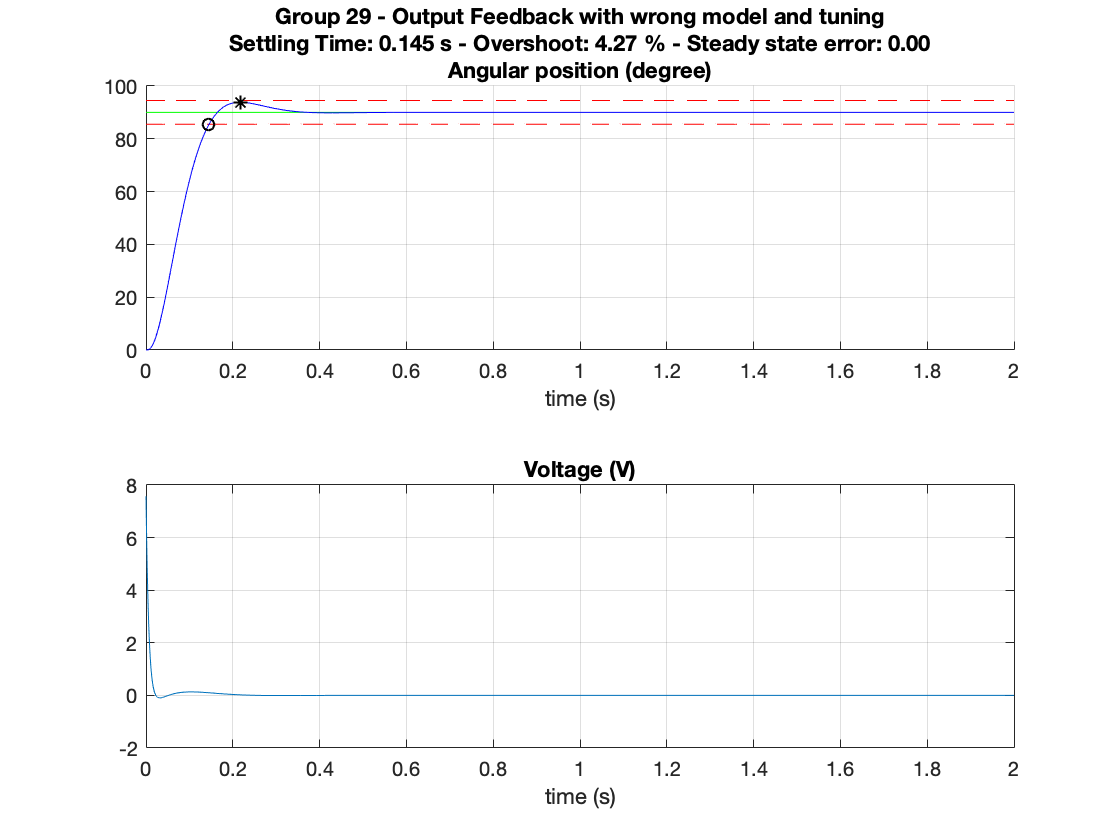



w = w(:)'; % make the output a row array
v = -K * lsim(ss(Hcl.A, Hcl.B, [zeros(3), eye(3)], 0), N*r, t)' + N * r; % simulate the command

customStep(sprintf('Group %02d - Output Feedback with wrong model and tuning',GroupNumber), t, w, r, v)

% What do you observe
% we observe that we now obtain the same plot as in the first two questions

## **4. Disturbance and Integral Design**

## *4.1 Experiment with an additive disturbance*

In this section we want to study the effects of a voltage disturbance on the state feedback controller. For this, we will simulate the effects of an additive disturbance into the voltage command of value $d = 4 V$ at time = 1s.

To simplify the problem, we will consider that the whole state is available, that we know the exact model of the DC Motor (same in section 1), and that we have designed a full feedback controller $K$, and $N$.

## Question 8 (0 marks)

What do you expect to happen to the angular position of the DC motor after applying a voltage command $d = 4 V$ at time = 1s ?

% [Answer here]
%

Let's simulate the result of adding such a disturbance in the closed-loop system

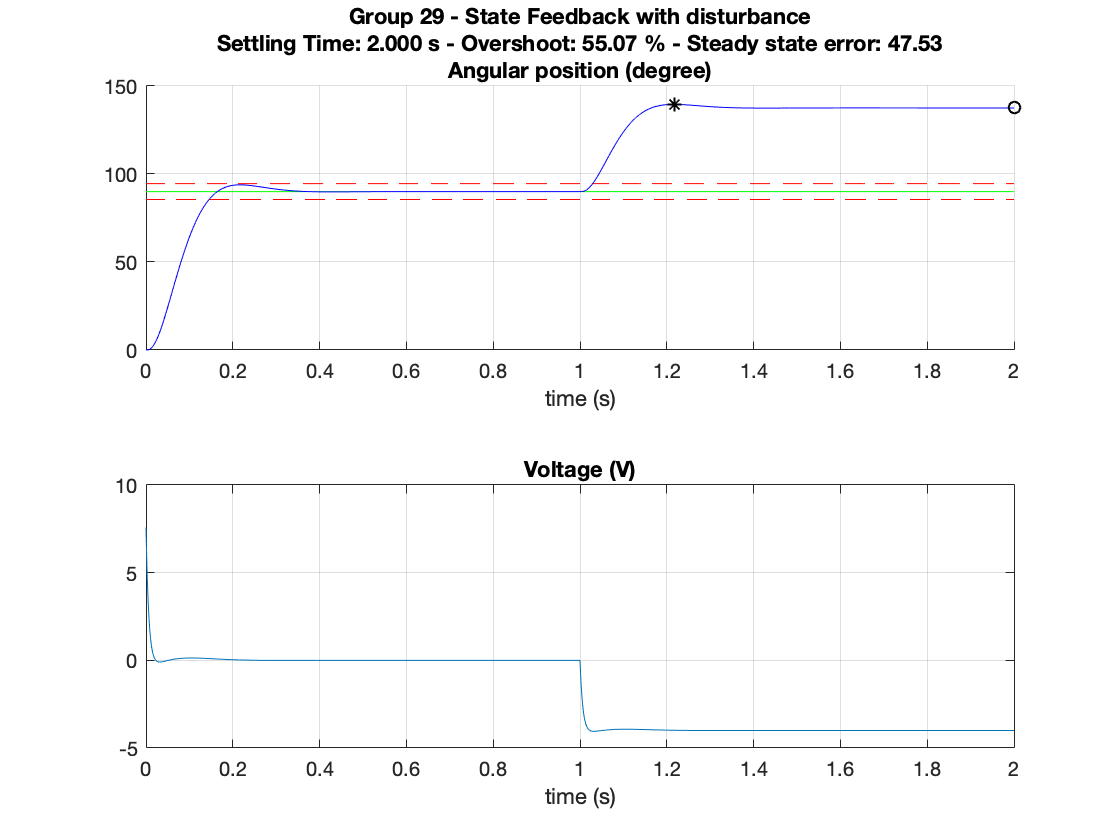

K = place(A, B, Kpoles);

d = zeros(size(t));
d(t >= 1) = 4; % disturbance signal

Hcl = ss(A-B*K, B, C, 0); % define the closed loop system
w = lsim(Hcl, N*r+d, t)'; % simulate the output
v = -K * lsim(ss(Hcl.A, Hcl.B, eye(3), 0), N*r+d, t)' + N * r; % simulate the command

customStep(sprintf('Group %02d - State Feedback with disturbance',GroupNumber), t, w, r, v)

## Question 9 (0.5 marks)

What is the steady state error? What is the closed-loop system type ?

% [Answer here]
%steady state error as seen in graph is 47.53. this is a type 0 CL system

## *4.2 state feedback with integral term*

We can add an integral term to the feedback controller to increase the type of the system. The integral equation is


$$ x_n(t) = r(t) - C x(t) $$


The augmented system is


$$ x_{aug}(t) = \pmatrix{ x(t) \cr x_n(t)} $$


and the feedback law is:


$$ v(t) = -K x(t) + K_e x_n(t) $$


The equivalent system can be seen as a closed-loop system where the open-loop dynamics is defined by


$$ \tilde{A} = \pmatrix{ A & 0 \cr -C & 0} $$



$$ \tilde{B} = \pmatrix{ B \cr 0} $$


and a unity feedback


$$ v(t) = -\pmatrix{ K & -K_e} x_{aug}(t)$$


## Question 10 (1.5 marks)

- Design $K$ and $Ke$ such as the poles of the feedback system are: $-15 \pm 15 j$, and $-150 \pm 150 j$.

- Complete the code to run the simulation.

- What do you observe ?

% 1 - [Answer here] use place in the augmented closed-loop with integral
% system
p1d = -15 + 15i;
p2d = -15 - 15i;
p3d = -150 * (1 + 1i);
p4d = -150 * (1 - 1i);

A0=[0;0;0]

A0 =      0
     0
     0


poles=[p1d,p2d,p3d,p4d]

poles =    1.0e+02 *

 -0.150000000000000 + 0.150000000000000i -0.150000000000000 - 0.150000000000000i -1.500000000000000 - 1.500000000000000i -1.500000000000000 + 1.500000000000000i



Atilde = [A, A0; -C, 0]

Atilde =                    0   1.000000000000000                   0                   0
                   0  -0.002000000000000  70.000000000000000                   0
                   0  -7.000000000000001 -20.000000000000000                   0
  -1.000000000000000                   0                   0                   0


Btilde = [B; 0]

Btilde =      0
     0
   200
     0


setK = place(Atilde, Btilde, poles)

setK =    1.0e+03 *

   0.106071428571461   0.003854238571715   0.001549990000000  -1.446428571428979


K = setK(1:3)

K =    1.0e+02 *

   1.060714285714605   0.038542385717155   0.015499900000005


Ke = -setK(4)

Ke =      1.446428571428979e+03


% 2 - Run the experiment

d = zeros(size(t));
d(t >= 1) = 4; % disturbance signal

% define the augmented closed-loop system

AtildeCl = Atilde - Btilde*setK

AtildeCl =    1.0e+05 *

                   0   0.000010000000000                   0                   0
                   0  -0.000000020000000   0.000700000000000                   0
  -0.212142857142921  -0.007778477143431  -0.003299980000001   2.892857142857958
  -0.000010000000000                   0                   0                   0


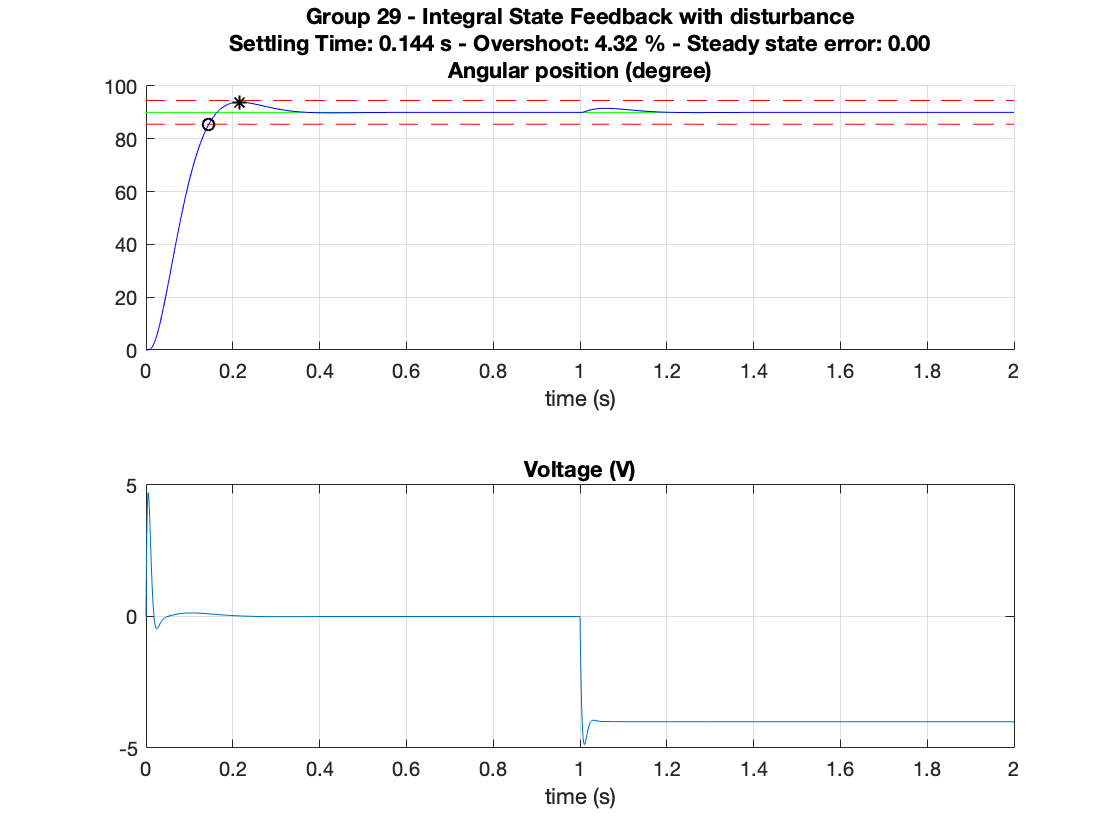



% simulate the output
yr = lsim(ss(AtildeCl, [0; 0; 0; 1], [1, 0, 0, 0], 0), r, t)'; %response to reference
yd = lsim(ss(AtildeCl, Btilde, [1, 0, 0, 0], 0), d, t)'; %response to disturbance
w = yr + yd;

v = -[K, -Ke] * lsim(ss(AtildeCl, [[0; 0; 0; 1], Btilde], eye(4), 0), [r; d], t)'; % simulate the command

customStep(sprintf('Group %02d - Integral State Feedback with disturbance',GroupNumber), t, w, r, v)

% 3 - What do you observe ?
%it can be observed that there is 0 steady-state error and that the graph is similar
%to the first two questions. Also, the voltage drops from 5 to -5

## **5. Useful Functions**

## *5.1 Custom step response*

function customStep(figTitle, t, w, r, v)
% calculate response characteristics and plot results
settlingTimeIdx = find(round((w - 0.95 * r)*180/pi, 1) <= 0.05 | round((w - 1.05 * r)*180/pi, 2) >= -0.05, 1, 'last');
[~, overshootIdx] = max(w);
steadyStateError = (180 / pi) * (w(end) - r(end));

figure;
clf;
hold on;
subplot(2, 1, 1)
hold on;
plot(t, (180 / pi)*0.95*r, '--r');
plot(t, (180 / pi)*1.05*r, '--r');
plot(t, (180 / pi)*r, 'g');
plot(t, (180 / pi)*w, 'b');
plot(t(settlingTimeIdx), (180 / pi)*w(settlingTimeIdx), 'ok')
plot(t(overshootIdx), (180 / pi)*w(overshootIdx), '*k')
grid on;
title(sprintf(['%s\n', ...
    'Settling Time: %4.3f s - Overshoot: %03.2f %% - Steady state error: %3.2f\n', ...
    'Angular position (degree)'], ...
    figTitle, ...
    t(settlingTimeIdx), ...
    100*(w(overshootIdx) - r(end))/r(end), ...
    steadyStateError))
xlabel('time (s)')
subplot(2, 1, 2)
plot(t, v);
grid on;
title('Voltage (V)');
xlabel('time (s)')
drawnow;
end